# post processing via optimization

clear, close all; clc;

### state space

Set up state space world of TWIPR including it's state vector (+ constraints) and input vector (+ constraints). Map state space into configuration space for visualization of the planning results.

% state space constraints
pitch_max             = deg2rad(90);
pitch_min             = deg2rad(-90);
pitch_velocity_max    = 2*pi;
pitch_velocity_min    = -2*pi;
position_max          = 6;
position_min          = -0.25;
position_velocity_max = 2;
position_velocity_min = -2;
psiD_max              = 400 * 0.75;
psiD_min              = -400 * 0.75;
xmax = [pitch_max; pitch_velocity_max; position_max; position_velocity_max; psiD_max];
xmin = [pitch_min; pitch_velocity_min; position_min; position_velocity_min; psiD_min];
% action space constraints. 75% for more conservative approach
umax = [2; 1] * 0.75;
umin = [-2; -1] * 0.75;
% handler for state space to config space function
x2y_func = @twipr_x2y;

% set up state space world
statespace = CKinodynamicConfigWorld(xmax, xmin, umax, umin, x2y_func);
% Load our obstacle polygon
load('1_Data/obstacle_0.6m.mat');
% load('1_Data/obstacle_x0.2m_z0.3.mat');
% Add the obstacle to our world
statespace.addObstacle(obstacle_polygon);

### local motion planning

Initialize local motion planning properties.

% Load TWIPR open-loop dynamic model to be used for lmp
chabo_open_loop_model = load("1_Data\chaboEC60_ol_dynamics_disc.mat");
% Function to forward simulate the twipr dynamics to determine state trajectories that result from the planned input trajectories 
% (does not have to use the same model as the Local Motion Planning)
forward_sim_func      = @(x, u)forward_sim(x, u, chabo_open_loop_model.A, chabo_open_loop_model.B); 

% Maximum number of samples per LMP between state nodes
Nmax = 100;
% Setup the local motion planning dynamics matrizes
[ANc,RIc] = lmp_precompute_mimo(Nmax, chabo_open_loop_model.A, chabo_open_loop_model.B); % Can be removed
% LMP function
% lmp_func is a function handle which covers all parameters but xI and xG
% returns input trajectory u between two local goals
lmp_func = @(xI, xG)lmp_time_opt_xcon_precomp_mimo(xI, xG,...
                                              umax, umin,...
                                              psiD_max, psiD_min, ...
                                              Nmax,...
                                              ANc, RIc,...
                                              chabo_open_loop_model);

## import data

xI = [0; 0; 0; 0; 0];     
xG = [0; 0; 3.5; 0; 0];
load('backwardDive3_raw.mat');
UP = UP_sel{1};
XP = XP_sel{1};

### Post Processing

Post processing to make paths more optimal in terms of dynamic

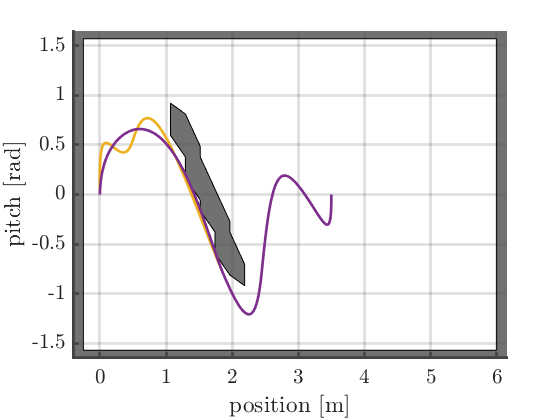

sel = 1;

% Let's make the planned trajectory more beautiful
[Xnew, Unew] = trajectoryPostProcessing_mimo(xI, xG, XP, UP, statespace, lmp_func, forward_sim_func);
figure;
statespace.draw();
plotStateTrajectoryInCSpace(XP);
plotStateTrajectoryInCSpace(Xnew);

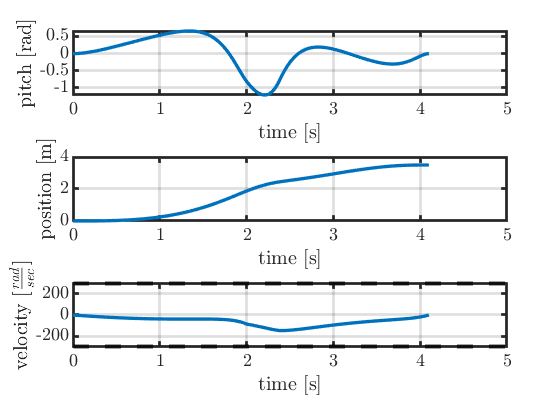

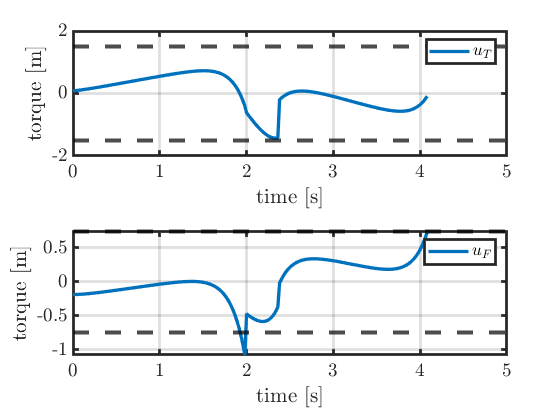

plotStateTrajectoriesOverTime_mimo(Xnew, Unew, umax, umin, psiD_max, psiD_min);

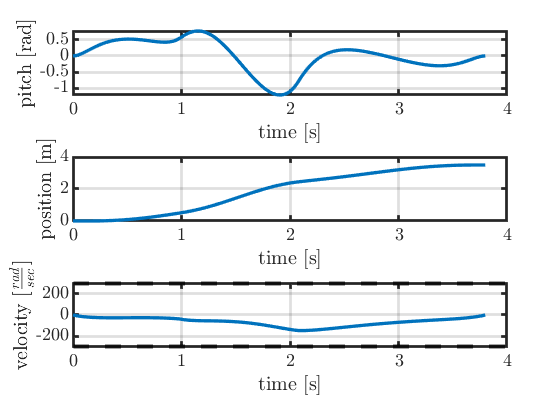

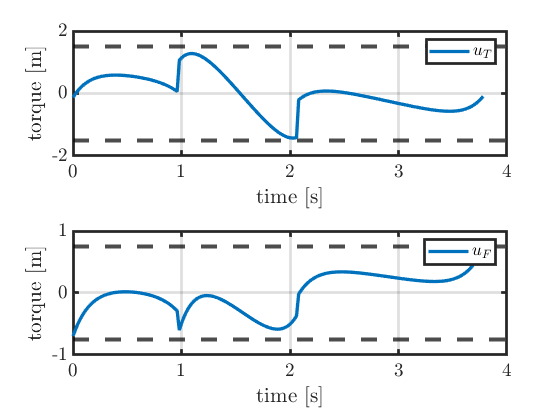

plotStateTrajectoriesOverTime_mimo(XP, UP, umax, umin, psiD_max, psiD_min);

## animation

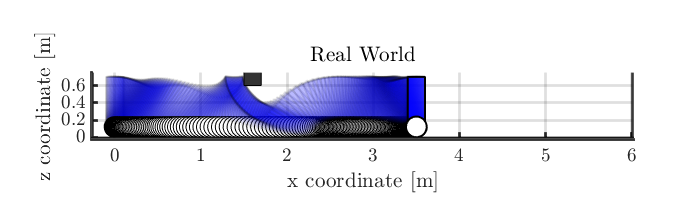

% Let's watch the planned trajectory in the real-world
load('1_Data/real_world_obst_0.6m.mat');
% real_world.mObstacles{1} = obstacle_polygon;
animate_movement_real_world(real_world, XP(1,:),XP(3,:));

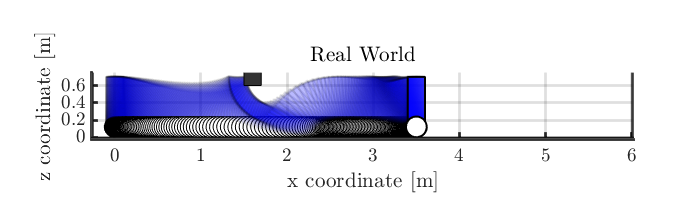

animate_movement_real_world(real_world, Xnew(1,:),Xnew(3,:));